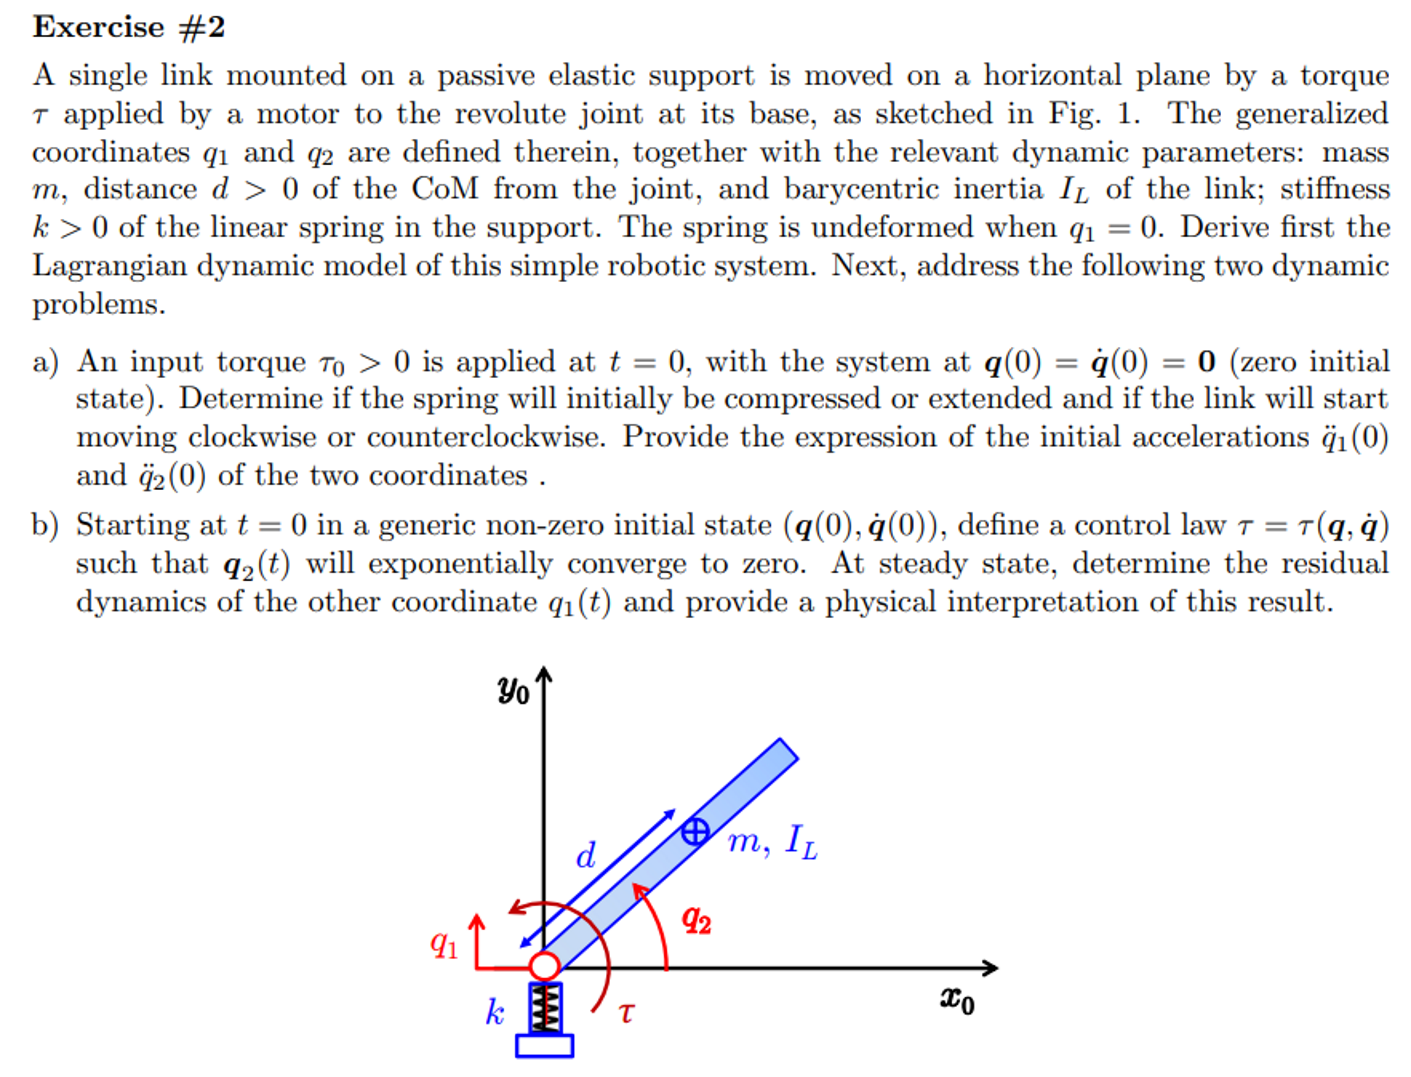

syms q1 q2 q_dot_1 q_dot_2 real
syms m I_L d k positive

% Total Kinetic energy
y = q1+d*sin(q2);
x = d*cos(q2);

vx = diff(x,q1)*q_dot_1+diff(x,q2)*q_dot_2;
vy = diff(y,q1)*q_dot_1+diff(y,q2)*q_dot_2;

T = 0.5*m*[vx vy]*[vx; vy;]+0.5*I_L*q_dot_2^2

$$T = \frac{m\,{\left({\dot{q}}_{1}+d\,{\dot{q}}_{2}\,\cos\left(q_{2}\right)\right)}^{2}}{2}+\frac{I_{L}\,{{\dot{q}}_{2}}^{2}}{2}+\frac{d^{2}\,m\,{{\dot{q}}_{2}}^{2}\,{\sin\left(q_{2}\right)}^{2}}{2}$$


% Inertia Matrix
M11 = diff(diff(T, q_dot_1), q_dot_1);
M12 = diff(diff(T, q_dot_1), q_dot_2);
M21 = diff(diff(T, q_dot_2), q_dot_1);
M22 = diff(diff(T, q_dot_2), q_dot_2);

M = [M11, M12;
     M21, M22;];
M = simplify(M)

$$M = \left(\begin{array}{cc} m & d\,m\,\cos\left(q_{2}\right)\\ d\,m\,\cos\left(q_{2}\right) & m\,d^{2}+I_{L} \end{array}\right)$$


% Coriolis and Centrifugal force
q  = [q1; q2;];
dq = [q_dot_1; q_dot_2;];
C = sym(zeros(2,2));

for i = 1:2
    for j = 1:2
        tmp = 0;
        for k = 1:2
            tmp = tmp + 0.5 * ( ...
                diff(M(i,j), q(k)) + ...
                diff(M(i,k), q(j)) - ...
                diff(M(k,j), q(i)) ) * dq(k);
        end
        C(i,j) = simplify(tmp);  % semplifico
    end
end

c_vec = simplify(C * dq);

disp('La matrice di Coriolis C(q,dq) è:');

La matrice di Coriolis C(q,dq) è:


disp(C);

$$\left(\begin{array}{cc} 0 & -d\,m\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 \end{array}\right)$$


disp('Il vettore c(q,dq) = C(q,dq)*dq è:');

Il vettore c(q,dq) = C(q,dq)*dq è:


disp(c_vec);

$$\left(\begin{array}{c} -d\,m\,{{\dot{q}}_{2}}^{2}\,\sin\left(q_{2}\right)\\ 0 \end{array}\right)$$